# Exhaustive Search (Kapsamlı Arama)

## Tanımı ve Temel Prensibi

Exhaustive search (Brute Force Search) türev (gradient) bilgisine ihtiyaç duymayan en basit arama metodudur.

Bir fonksiyonun tanımmlı olduğu aralıkta belirli  sayıda örneklenir, fonksiyon bu noktada hesaplanır ve en küçük değerine sahip nokta, minimum kabul edilir.

Matematiksel olarak


$$x^{*\;} ={\mathrm{argmin}\;f}_{\;} \left(x\right)\;\;\;\;\;\;\;\;\;x\in \left\lbrack a,b\right\rbrack$$


Burada f(x) fonksiyonu sürekli olmak zorunda değildir. Sadece belirli bir daralıkta değerlendirilebilir olması yeterlidir.

Bu yöntem, tüm olası çözümleri türev, yön bilgisi veya rastgelelik kullanmadan taradığı için deterministik bir yöntemdir.

## Algoritma

- Aralık belirlenir $\left\lbrack a,b\right\rbrack$

- Nokta sayısı $N$ seçilir.

- Adım büyüklüğü hesaplanır.

                
$$\Delta x=\frac{b-a}{N-1}$$


- Her $x_i =a+i\Delta x$ için $f\left(x\right)\;$$\mathrm{değeri}\;\mathrm{heaplan}\i \mathrm{r}\ldotp$

- En küçük veya enbüyük $f\left(x_i \right)\;$değerine sahip nokta bulunur.

## Avantajları ve Dezavantajları

## Tek Değişkenli Örnek 

Fonksiyon


$$f\left(x\right)={\left(x-2\right)}^2 +1$$


Aralık $\left\lbrack 0,4\right\rbrack$  nokta sayısı $N=9$

**Sonuç:**


$$x^* =2\ldotp 0,{\;f}_{\min } =1\ldotp 0$$


%% Tek Değişkenli Exhaustive Search
clc; clear; close all;

% --- Parametreler ---
a = 0;             % Aralık başlangıcı
b = 4;             % Aralık sonu
N = 9;             % Nokta sayısı

% --- Noktaları oluştur ---
x = linspace(a, b, N);   % 0, 0.5, 1.0, ..., 4.0
f = (x - 2).^2 + 1;      % f(x) = (x-2)^2 + 1

% --- Minimumu bul ---
[f_min, idx_min] = min(f);
x_min = x(idx_min);

% --- Sonuçları yazdır ---
fprintf('Minimum değer: f(%.2f) = %.2f\n', x_min, f_min);

Minimum değer: f(2.00) = 1.00


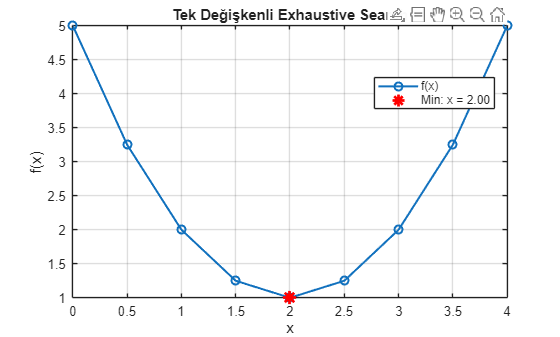


% --- Görselleştirme ---
figure
plot(x, f, '-o', 'LineWidth', 1.5)
hold on;
plot(x_min, f_min, 'r*', 'MarkerSize', 10, 'LineWidth', 2);
title('Tek Değişkenli Exhaustive Search');
xlabel('x');
ylabel('f(x)');
grid on;
legend('f(x)', sprintf('Min: x = %.2f', x_min), 'Location', 'best');

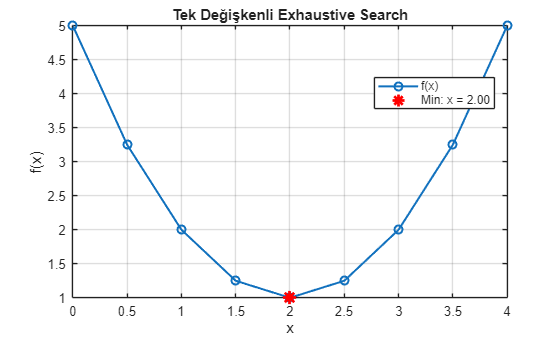

## Çok Değişkenli Örnek 

Fonksiyon


$$f\left(x,y\right)={\left(x-1\right)}^2 +{\left(y-2\right)}^2$$


Aralık $x\in \left\lbrack 0,2\right\rbrack ,y\in \left\lbrack 0,3\right\rbrack \;$  

Adım aralıkları:  $\Delta x=\Delta y=1$

% --- Aralıklar ve örnekleme adımı ---
x = 0:0.1:2;     % x = [0, 1, 2]
y = 0:0.1:3;     % y = [0, 1, 2, 3]

% --- Izgara oluştur ---
[X, Y] = meshgrid(x, y);

% --- Fonksiyon tanımı ---
F = (X - 1).^2 + (Y - 2).^2;

% --- Minimumu bul ---
[F_min, idx] = min(F(:));
x_min = X(idx);
y_min = Y(idx);

% --- Sonucu yazdır ---
fprintf('Minimum değer: f(%.2f, %.2f) = %.2f\n', x_min, y_min, F_min);

Minimum değer: f(1.00, 2.00) = 0.00


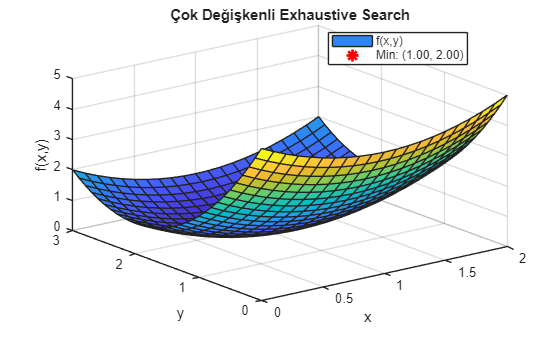


% --- 3D yüzey grafiği ---
figure
surf(X, Y, F);
title('Çok Değişkenli Exhaustive Search');
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
hold on;
plot3(x_min, y_min, F_min, 'r*', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
legend('f(x,y)', sprintf('Min: (%.2f, %.2f)', x_min, y_min), 'Location', 'best');

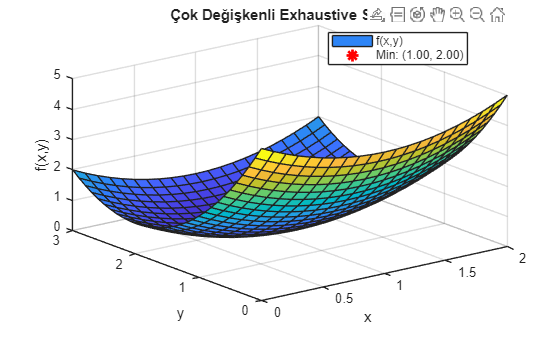

## Kaynaklar

[1] - “Exhaustive Search, Combinatorial Optimization and Enumeration” – ETH Zürich Lecture Notes